randian = 0.01745329;

#### We know: 

The boats postion (x,y)

The boats angle realtive to magnigtic north in decimal degrees 

The (x,y) of the target posion

### Other factors 

The koordinates sets lie in an abitarry postion.

we do not have a global origin. 

We need to create a local orgin. maybe. 

### The Goal.

To optain the angle that to boat should turn to point towards the target. 

# Finding the length to target and angle to target

To create a funtion, who will return the distance and angle from the boats pos to the next target.

boat = [1 1 450]

boat =      1     1    45


target = [7 5]

target =      7     5


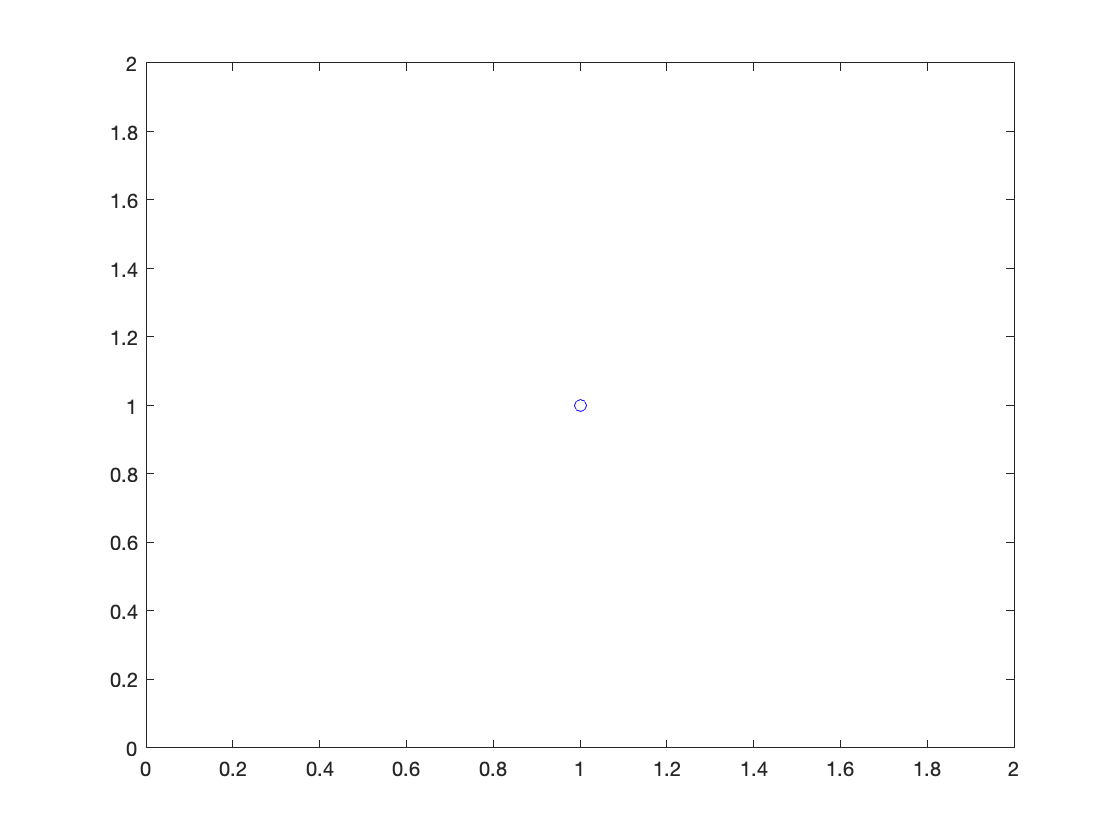

L = '-'

Not enough input arguments.

Error in navigation>drawVector (line 100)
    L = line(lineX, lineY);

Error in navigation>drawBoat (line 117)
    drawVector(originUnit,boat(1,1:2));

Error in 

clf;
drawBoatAndTarget(boat, target)

title('the boat and the target at the starting points')
axis([0 10 0 10])
radian = 0.01745329;
degree = 57.29578;
% determinging the the unit vector of the direction of the boat
    
    % take the boat direction and multiply it by the radian constant.
    boatDir = boat(3)*radian;
    
    % the unit vector is converted from polar cordinates to cardisan
    % coordiantes 
        % x = r*con(Theta)
        % y = r*sin(Theta)
    originUnit = [1*cos(boatDir) 1*sin(boatDir)];
    
    % the unit vector gets the boat as origin by multiplin the
    % corresponding coordiantes.
    relativeUnit = boat(1:1:2)+originUnit;

% determining the vector between the boats coordinates and the target
% coordinates

    % to detmin the vector between two points/vectors, simpli substract
    % them
    
    V_boat_to_target = target(1,:)-boat(1,(1:2));
    

% calculating the length of the vector between the boat and target
    % since we are in a 2d plane, the length between target an boat is
    % simply pytagaros
    length_to_target = sqrt(V_boat_to_target(1)^2 + V_boat_to_target(2)^2)
    
% calculating the angle between the two vecotes.
    
    % Calculating the angle between two vectors. 
    dot_boat_target = boat(1)*V_boat_to_target(1)+boat(2)*V_boat_to_target(2)
    length_boat = sqrt(boat(1)^2 + boat(2)^2)
    length_target = sqrt(V_boat_to_target(1)^2 + V_boat_to_target(2)^2)
    
    angle_to_target = acos(dot_boat_target / (length_boat * length_target))
    angle_to_target*57.29578


$$\cos \left(\theta \right)=\frac{\overrightarrow{\textrm{boat}} \bullet \overrightarrow{\textrm{target}} }{\left|\right|\overrightarrow{\textrm{boat}} \left|\right|\cdot \left|\right|\overrightarrow{\textrm{target}} \left|\right|}$$


The cosine of the angle is giving by the dot product of the vectors devided by thier absulut values multiplied by each other. 

The dot product is given by:


$$\textrm{dot}\left(v,u\right)=v_1 \cdot \;u_1 +v_2 \cdot \;u_2 +v_n \cdot \;u_n$$


And the length of a vector, is simply the squre root of the vector dotted with it self


$$\left|\right|v\left|\right|=\sqrt{\;v\bullet v}=\sqrt{v_1^2 +v_2^2 +v_n^2 }$$


Or, in other words, pytagoros. 

# Turn a vector formulars


$$\begin{array}{l}
\textrm{Rotation}\;\textrm{matrix}\ldotp \ldotp \ldotp \textrm{dont}\;\textrm{know}\;\textrm{if}\;\textrm{its}\;\textrm{applyes}\;a\;\textrm{roll}\\
R=\left\lbrack \begin{array}{cc}
\cos \;\theta  & -\sin \;\theta \\
\sin \;\theta  & \cos \;\theta 
\end{array}\right\rbrack ,\textrm{Rotation}\;\textrm{matrix}\;\textrm{on}\;\textrm{its}\;\textrm{own}\\
\textrm{Rv}=\left\lbrack \begin{array}{cc}
\cos \;\theta  & -\sin \;\theta \\
\sin \;\theta  & \cos \;\theta 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack ,\textrm{rotation}\;\textrm{matrix}\;\textrm{applyed}\;\textrm{to}\;\textrm{vector}\\
\textrm{Rv}\;=\left\lbrack \begin{array}{cc}
\cos \;\theta_{\textrm{roation}}  & -\sin \;\theta_{\textrm{rotation}} \\
\sin \;\theta_{\textrm{rotatin}}  & \cos \;\theta_{\textrm{rotation}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1\cdot \cos \;\theta_{\textrm{boat}} \\
1\cdot \sin \;\theta_{\textrm{boat}} 
\end{array}\right\rbrack ,\textrm{Rotation}\;\textrm{matrix}\;\textrm{applyed}\;\textrm{to}\;\textrm{unit}\;\textrm{vector}\;\textrm{optained}\\
\;\textrm{from}\;\textrm{convertion}\;\textrm{from}\;\textrm{polar}\;\textrm{to}\;\textrm{catesian}\;\textrm{coordinates}\ldotp 
\end{array}$$


# Testing printing funktionality

clear
boatPos = [1 2]

boatPos =      1     2


boatDirDegree = 80;
boat = [boatPos boatDirDegree]

boat =      1     2    80



clf;
drawVector([2 2], [1 1])

O =      1     1


V =      2     2


lineX =      1     2


lineY =      1     2


Index in position 1 exceeds array bounds (must not exceed 1).

Error in navigation>drawVector (line 105)
    L = line(lineX, lineY);

%boatUv = drawBoat(boat);

title("boat and goal position relative")

axis([0 10 0 10])

goal = [4 6; 7 8];
drawTargets(goal);


To optain the vector between the boat and the goal

Their vectors can be substracted. The order does however matter. 


$$v_{\textrm{togoal}} =v_{\textrm{goal}} -v_{\textrm{boat}}$$


L = drawVector(goal(1,:)-boat(1,(1:2)), boat(1,(1:2)), 'r');
clf;
drawBoatAndTarget(boat, goal)
axis([0 10 0 10]);



function [L] = drawVector(vector, origen)
    color = 'r';
    line = 'l';
    if nargin == 4
        O = origen;
        V = vector;
        C = color;
        l = line;
    elseif nargin == 3
        O = origen;
        V = vector;
        C = color;
        l = '-';
    elseif nargin == 2
        O = origen;
        V = vector;
        C = 'blue';
        l = '-';
    elseif nargin == 1
        O = [0, 0];
        V = vector;
        C = 'blue';
        l = '-';
    end
    O
    V
    
    lineX = [O(1) V(1)];
    lineY = [O(2) V(2)];
    lineX
    lineY
    L = line(lineX, lineY);
    L.Color = C;
    L.LineStyle = l;

end
% methoed to draw boat postion and its direction, visulised as a unit
% vector.
% takes a boat object containing [x-pos y-pos -DirInDegrees]
function [originUnit, relativeUnit, P ] = drawBoat(boat)
    % constants
    radian = 0.01745329;
    
    boatDir = boat(3)*radian;
    originUnit = [1*cos(boatDir) 1*sin(boatDir)];
    relativeUnit = boat(1:1:2)+originUnit;
    P = plot(boat(1),boat(2), 'bo');
    hold on
    drawVector(originUnit,boat(:,1:2));
    

end

% Plots the number of targets as green stares.
function [P] = drawTargets(targets)
    P = plot(targets(:,1),targets(:,2),'g*');
end


% combines drawBoat, DrawTargets in one call. 
% calculates the vector drawn from the boat to the first entry in targets
function [V_boat_to_target] = drawBoatAndTarget(boat, targets)
    drawBoat(boat);
    drawTargets(targets);
    V_boat_to_target = targets(1,:)-boat(1,(1:2));
    drawVector(V_boat_to_target, boat(1,(1:2)), 'r','.');
end